% This script is used to determine the optimum cutt-off frequency for filtering a signal, based on Winter's metode [1,2].
% Ce script permet de déterminer la fréquence de coupe optimale pour filtrer un signal en se basant sur la méthode de Winter [1,2].

% [1]	D. A. Winter, Biomechanics and Motor Control of Human Movement. Wiley, 1990.
% [2]	D. Mullineaux, « USING A BREAKPOINT TO DETERMINE THE OPTIMAL CUT-OFF FREQUENCY », ISBS Proceedings Archive, vol. 35, no 1, oct. 2017, [En ligne]. Disponible sur: https://commons.nmu.edu/isbs/vol35/iss1/140

%Jason Dellai 2023

clear variables

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%import_data
Data_base = readtable("Sample_Kinematic_Data.txt");

%Choose a 1D vector
Data = Data_base.X1;

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%You should ajust those parameters 

%Sampling parameters
Fsamp = 200;                     %sampling frequency 
cutoff_min = 0;                  %Filter cut-off tested minimum (can be set at 0)
cutoff_max = 20;                 %Filter cut-off tested maximum (can be set at Fsamp/2)
step_configuration = "StepSize"; % "StepNumber" or "stepsize" choose to precise the number of filter tested or the gap between 2 filters tested
step_number = 200;               %if step_configuration = "StepNumber" precise the number of filter tested between cutoff_min and cutoff_max
step_size = 0.1;                 %if step_configuration = "StepSize" precise the gap in Hz between 2 filters tested

%Filter choice
Custom_FiltFilt_Order = 2;       %You can choose the order of the filter, be carefull a high order may create NaN in your data

%Detection of breackpoint
Detection_auto_xlim = [];        %you can modify xlim for ginput eg.[0 10]
Detection_auto_ylim = [];        %you can modify ylim for ginput eg. [0 25]

%Graphic display
Disp_Plot = 1;                   %Disp graph 0 == OFF // 1 == ON
Filename = [];                   %Put file name in the title of the graph eg. "Filename"

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%Create a list of filter to be tested

%StepNumber mode
if step_configuration == "StepNumber";
    step = (cutoff_max-cutoff_min)/step_number;
    Filter_List = [cutoff_min:step:cutoff_max];
end

%StepSize mode
if step_configuration == "StepSize";
    Filter_List = [cutoff_min:step_size:cutoff_max];
end

%Verify first and last cut-off frequency tested
if Filter_List(1) == 0; %first filter should be greater than 0
    Filter_List(1) = Filter_List(2)/2;
end

if Filter_List(end) >= Fsamp/2; %last filter should be lower than Fsamp/2
    Filter_List(end) = [];
end

Residual_Error = zeros([1 length(Filter_List)]);

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%Calculate the RMSE for each filter

for Filter_Number = (1:length(Filter_List));

        %Function "FiltFilt" matlab
        %Configure Butter
        Wn = (Filter_List(Filter_Number)) / ((Fsamp)/2); % fequency expressed in % of Fnyqvuit
        [B,A]=butter(Custom_FiltFilt_Order,Wn,"low");

        %filter data for one filter
        Data_Filtered = filtfilt(B,A,Data);
   
    %calculate RMSE
    Data_RMSE = sqrt((Data_Filtered-Data).^2);
    Residual_Error(Filter_Number) = mean(Data_RMSE);
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%Determining the optimal cut-off frequency using the residual analysis of zero derivative by regression method (Winter, 1990)

%plot the residual error for each filter
figure;
enableDefaultInteractivity(gca);
set(gcf, 'Units', 'Normalized', 'OuterPosition', [0 0 1 1]);
plot(Filter_List,Residual_Error)
legend('Click on two points to create linear regression, the script will only read the x position of each points')

%if indicated, specify xlim and ylim
if not(isempty(Detection_auto_ylim)) ;
    ylim(Detection_auto_ylim)
end
if not(isempty(Detection_auto_xlim));
    xlim(Detection_auto_xlim)
end

%use ginput in order to place two points 
click = ginput(2);
First_click_x = click(1,1);
Second_click_x = click(2,1);
close()

%Find the coordinates of the points which coincide with the points set with
%ginput
First_click_y = Residual_Error(find(Filter_List >= First_click_x, 1, 'first'));
Second_click_y = Residual_Error(find(Filter_List >= Second_click_x, 1, 'first'));

%Calculate the slope of the linear regression
Coeff_Directeur = (Second_click_y-First_click_y)/(Second_click_x -First_click_x);

idx_First_click_x = (find(Filter_List >= First_click_x, 1, 'first'));
idx_Second_click_x = (find(Filter_List >= Second_click_x, 1, 'first'));

%find the Y-Intercept
Linear_fitting_temp = Coeff_Directeur*Filter_List;
Intercept = mean(Residual_Error(idx_First_click_x:idx_Second_click_x)-Linear_fitting_temp(idx_First_click_x:idx_Second_click_x));


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%Blue curve = plot(Filter_List,Residual_Error), 
%orange line = Linear Regression, 
%Yellow line = YIntersect,
%Purple line = Optimal Cut Off Frequency,

Cutt_Off_Frequency = Filter_List(find(Residual_Error <= Intercept, 1, 'first'))

Cutt_Off_Frequency = 5.2000

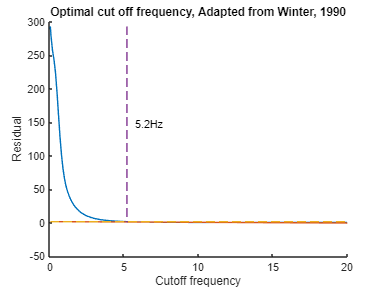


if Disp_Plot == 1;
    figure;
    Titre = "Optimal cut off frequency, Adapted from Winter, 1990";
    if not(isempty(Filename));
        Titre = Filename
    end
    title(Titre);
    Linear_fitting = Coeff_Directeur*Filter_List + Intercept;
    Origin_line = zeros([1 length(Filter_List)]) + Intercept;
    Cutt_Off_Frequency_line = zeros([1 length(Filter_List)]) + Cutt_Off_Frequency;
    hold on
    plot(Filter_List,Residual_Error)
    plot(Filter_List,Linear_fitting)
    plot(Filter_List,Origin_line,'--')
    plot(Cutt_Off_Frequency_line,Residual_Error,'--')
    xlabel("Cutoff frequency")
    ylabel("Residual")
    text(Cutt_Off_Frequency*1.1, Residual_Error(1)/2, {Cutt_Off_Frequency + "Hz"})
end


disp 'Cutt_Off_Frequency'

Cutt_Off_Frequency
